# Deflection Analysis of Bracket

This example shows how to analyze a 3-D mechanical part under an applied load using finite element analysis (FEA), reduce the response of maximum deflection versus material parameters and generate a FMU.

## Create Structural Analysis Model

The first step in solving a linear elasticity problem is to create a structural analysis model. This is a container that holds the geometry, structural material properties, damping parameters, body loads, boundary loads, boundary constraints, superelement interfaces, initial displacement and velocity, and mesh.

model = createpde('structural','static-solid');

## Import Geometry

Import an STL file of a simple bracket model using the `importGeometry` function. This function reconstructs the faces, edges and vertices of the model. It can merge some faces and edges, so the numbers can differ from those of the parent CAD model.

importGeometry(model,'BracketWithHole.stl');

Plot the geometry, displaying face labels.

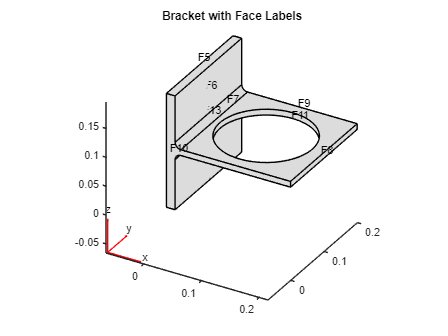

figure
pdegplot(model,'FaceLabels','on')
view(30,30);
title('Bracket with Face Labels')

## Specify Structural Properties of Material

Specify Young's modulus and Poisson's ratio of the material.

structuralProperties(model,'YoungsModulus',200e9, ...
                           'PoissonsRatio',0.3);

## Apply Boundary Conditions and Loads

The problem has two boundary conditions: the back face (face 4) is fixed, and the front face has an applied load. All other boundary conditions, by default, are free boundaries.

structuralBC(model,'Face',4,'Constraint','fixed');

Apply a distributed load in the negative $z$-direction to the front face (face 8).

structuralBoundaryLoad (model,'Face',8,'SurfaceTraction',[0;0;-1e4]);

## Generate Mesh

Generate and plot a mesh.

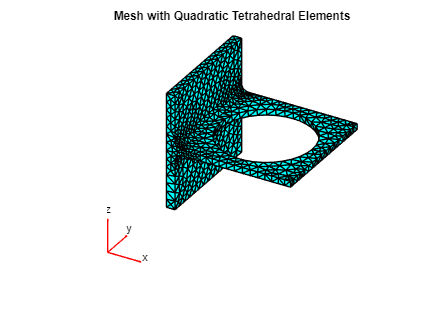

generateMesh(model);
figure
pdeplot3D(model)
title('Mesh with Quadratic Tetrahedral Elements');

## Create DOE of Material Properties

Create Latin Hypercube Sampling (LHS) doe of Young Modulus and Poisson ratio with Statistics and Machine Learning Toolbox.

rng default % For reproducibility
DOE = lhsdesign(10,2) % between 0 and 1

DOE =     0.2249    0.3159
    0.1745    0.8746
    0.8494    0.7186
    0.9301    0.1756
    0.0109    0.0071
    0.4041    0.5650
    0.3453    0.9803
    0.5861    0.4749
    0.6851    0.6384
    0.7742    0.2527


## Solve DOE models

Solve the case for all points of the DOE and get the maximum deflection in z direction.

Case 1 ------------

E = 1.2249e+11

nu = 0.0948

Maximal z deflection is 7.1914e-05 meters.

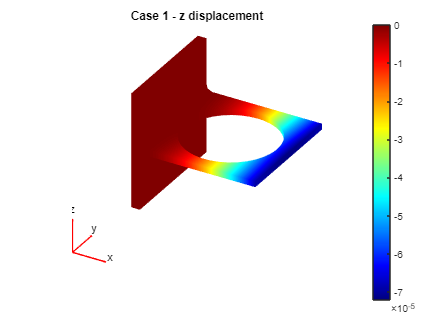

Case 2 ------------

E = 1.1745e+11

nu = 0.2624

Maximal z deflection is 7.54711e-05 meters.

Case 3 ------------

E = 1.8494e+11

nu = 0.2156

Maximal z deflection is 4.79026e-05 meters.

Case 4 ------------

E = 1.9301e+11

nu = 0.0527

Maximal z deflection is 4.54817e-05 meters.

Case 5 ------------

E = 1.0109e+11

nu = 0.0021

Maximal z deflection is 8.63918e-05 meters.

Case 6 ------------

E = 1.4041e+11

nu = 0.1695

Maximal z deflection is 6.30037e-05 meters.

Case 7 ------------

E = 1.3453e+11

nu = 0.2941

Maximal z deflection is 6.5877e-05 meters.

Case 8 ------------

E = 1.5861e+11

nu = 0.1425

Maximal z deflection is 5.57008e-05 meters.

Case 9 ------------

E = 1.6851e+11

nu = 0.1915

Maximal z deflection is 5.25399e-05 meters.

Case 10 ------------

E = 1.7742e+11

nu = 0.0758

Maximal z deflection is 4.95745e-05 meters.

ndoe = 10; % choose even
results = [];
minUzs = [];
Es = [];
nus = [];
for index = 1: ndoe

    fprintf('Case %d ------------', index)

    % parameters
    E = 100e9 + 100e9 * DOE(index, 1)
    nu = 0.3 * DOE(index, 2)
    Es(index) = E;
    nus(index) = nu;
    structuralProperties(model,'YoungsModulus',E, ...
                             'PoissonsRatio',nu);
    % solve
    result = solve(model);
    results = [results, result];

    % get maximal deflection
    minUz = abs(min(result.Displacement.uz));
    minUzs(index) = abs(minUz);
    fprintf('Maximal z deflection is %g meters.', minUz)

    % plot first result for visualization
    if index == 1
        figure
        pdeplot3D(model,'ColorMapData',result.Displacement.uz)
        title(sprintf('Case %d - z displacement', index))
        colormap('jet')
    end
end

## Visualize data

We plot the response surface for discrete points and interpolated surface.

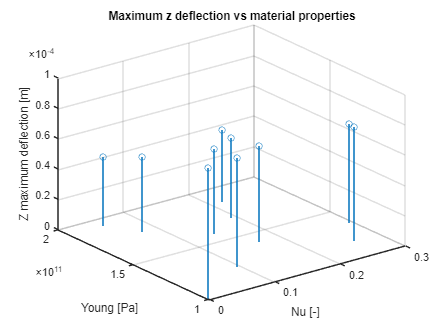

%Plot discrete points
x = nus;
y = Es;
z = minUzs;
figure(1)
stem3(x, y, z)
title('Maximum z deflection vs material properties')
xlabel('Nu [-]') 
ylabel('Young [Pa]') 
zlabel('Z maximum deflection [m]') 
grid on

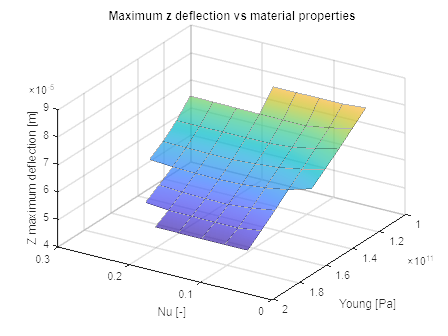

% Get grid representation from discrete points
xv = linspace(min(x), max(x), 10);
yv = linspace(min(y), max(y), 10);
[X,Y] = meshgrid(xv, yv);
Z = griddata(x,y,z,X,Y);

% Plot interactive figure
% figure(2)
hFig = figure;
hAxes = axes('Parent',hFig);
hPlot = surf(hAxes,X,Y,Z);
hPlot.FaceAlpha = 0.7;
hPlot.EdgeAlpha = 0.3;
hPlot.FaceColor = 'interp';
hPlot.EdgeColor = [0 0 0];
hPlot.EdgeLighting = 'gouraud';
% title ...etc
title('Maximum z deflection vs material properties')
xlabel('Nu [-]') 
ylabel('Young [Pa]') 
zlabel('Z maximum deflection [m]') 
view([-148.2000000 36.0000000])
rotate3d on;

## Additional Stats

Correlation input/outputs, PCA ...

% To be added

## Build ROM

We build a reduced model to link material properties (Young modulus, poisson ratio) to maximum deflection.

rng 'default'  % For reproducibility
A = [transpose(Es), transpose(nus),transpose(minUzs)];
trainingData = array2table(A);
trainingData.Properties.VariableNames(1:3) = {'Young','Poisson','Max Deflection'}

trainingData = 10×3 table
      Young        Poisson     Max Deflection
    __________    _________    ______________

    1.2249e+11     0.094778      7.1914e-05  
    1.1745e+11      0.26237      7.5471e-05  
    1.8494e+11      0.21557      4.7903e-05  
    1.9301e+11     0.052694      4.5482e-05  
    1.0109e+11    0.0021221      8.6392e-05  
    1.4041e+11       0.1695      6.3004e-05  
    1.3453e+11       0.2941      6.5877e-05  
    1.5861e+11      0.14247      5.5701e-05  
    1.6851e+11      0.19152       5.254e-05  
    1.7742e+11     0.075801      4.9575e-05  


Using the Regression Learner app.

First model, not ideal: SVM quadratic kernel.

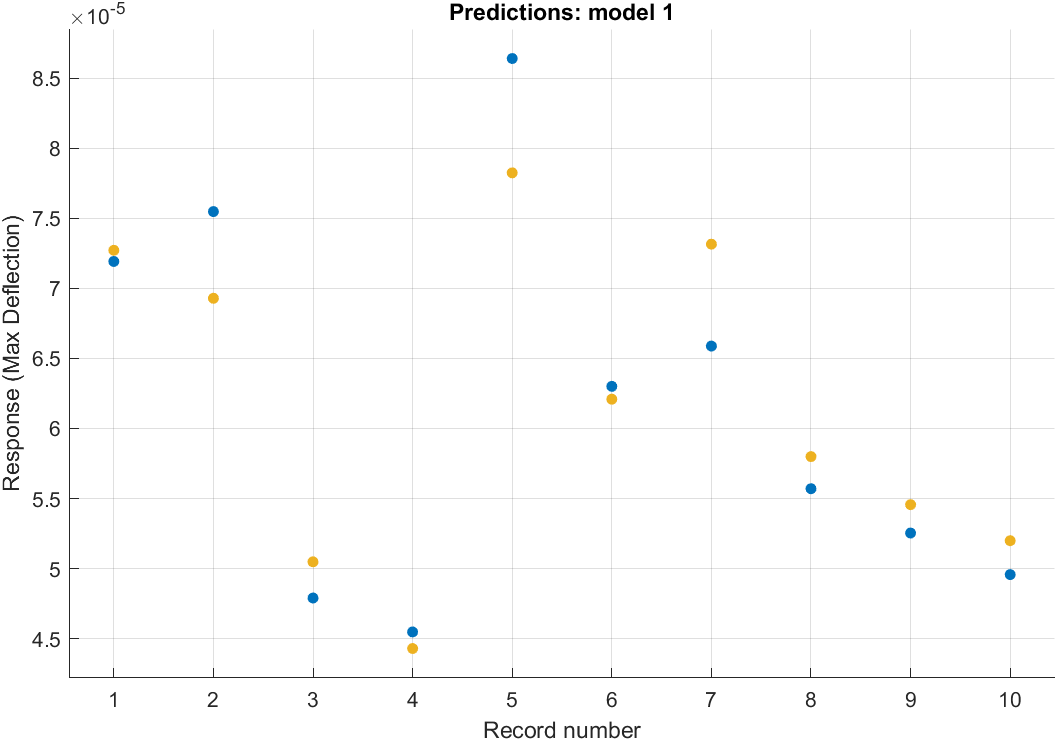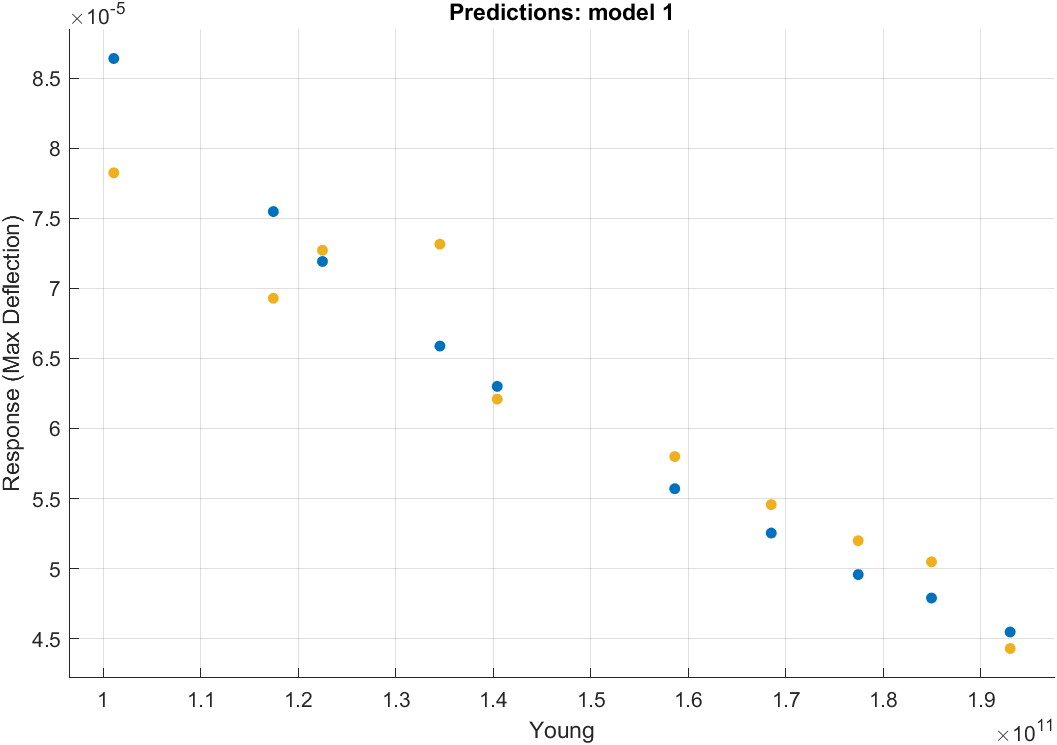

% Using the regression learner app to get the best model
[trainedModel, validationRMSE] = trainRegressionModel1(trainingData)

trainedModel = struct with fields:
           predictFcn: @(x)svmPredictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'Poisson'  'Young'}
        RegressionSVM: [1×1 RegressionSVM]
                About: 'This struct is a trained model exported from Regression Learner R2021b.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


validationRMSE = 2.6188e-06

Second model is better : SVM cubic kernel.

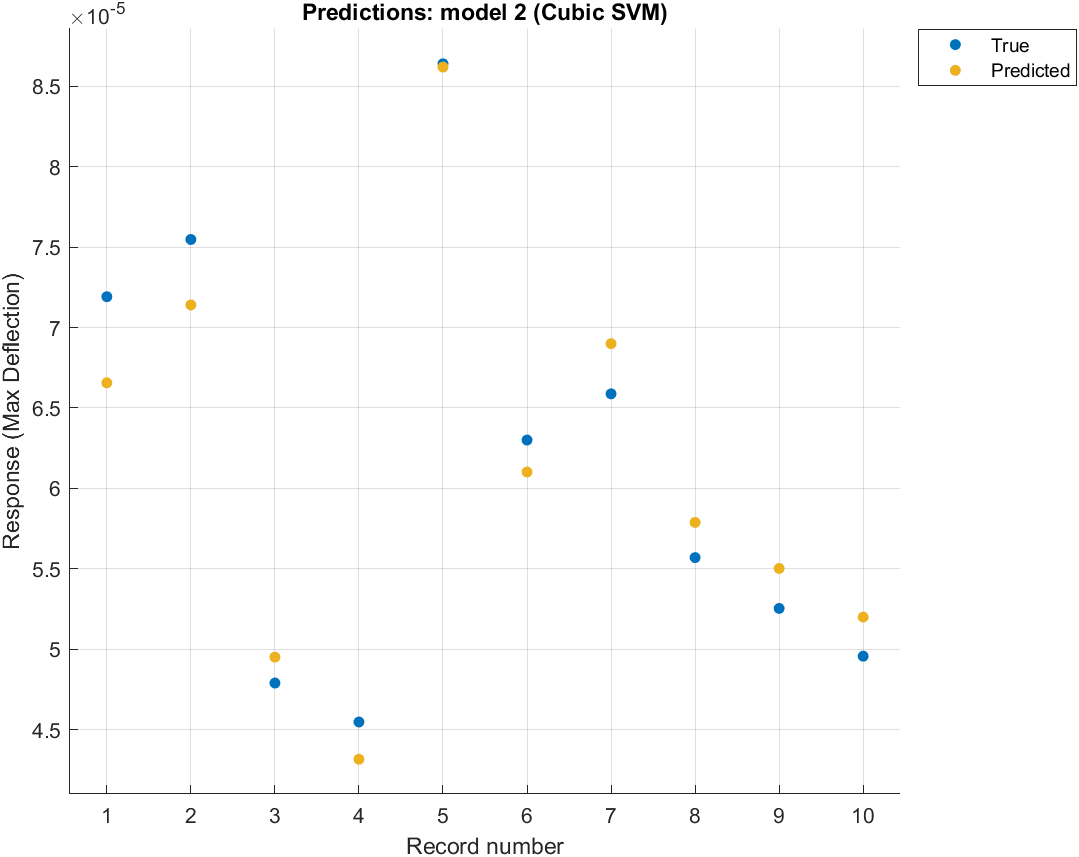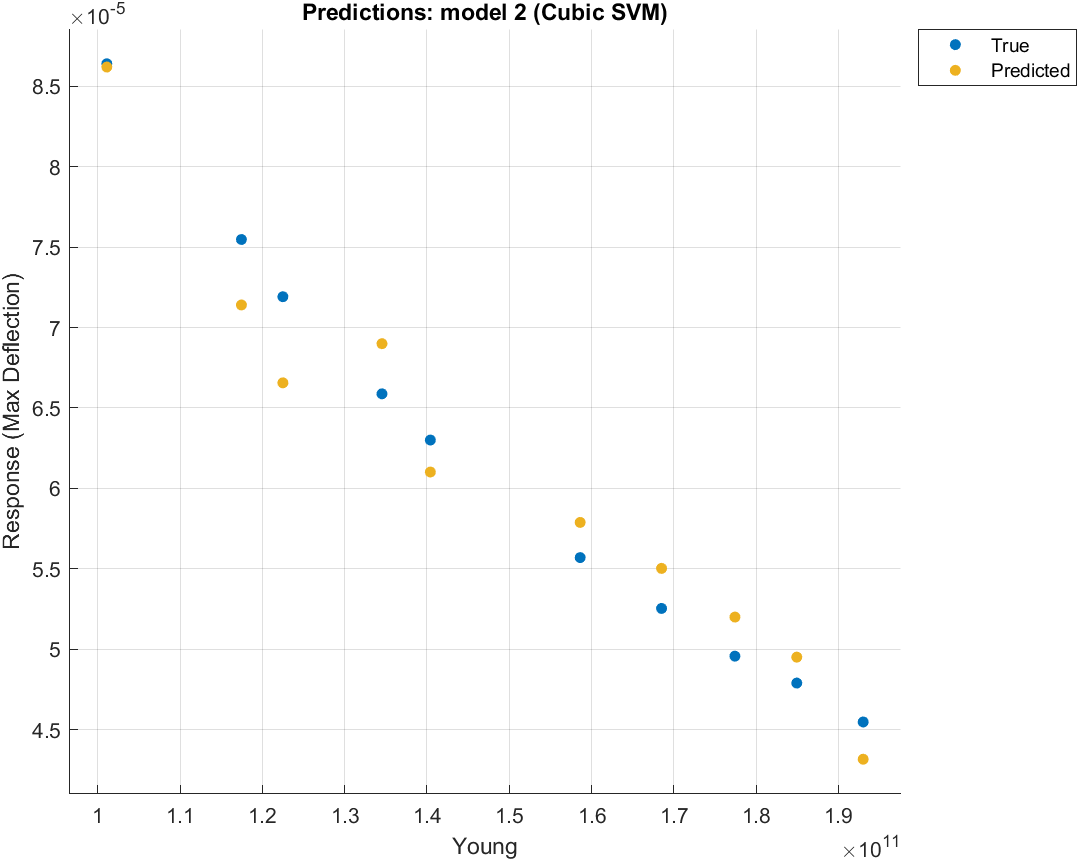

% Using the regression learner app to get the best model
[trainedModel, validationRMSE] = trainRegressionModel(trainingData);
svmMdl = trainedModel.RegressionSVM;


## Import SVM predict in SIMULINK

This generates programmatically a new simulink model and creates a SVM predict block.

% create empty SIMULINK model programmatically
% new_model('BracketRegressionSVMPredict')

Add with GUI a predict SVM block in simulink using the svmMdl

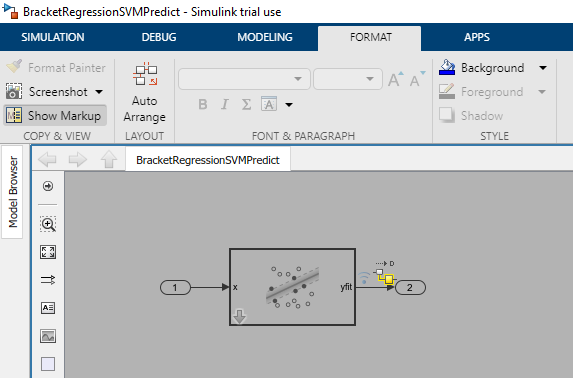

% Check SIMULINK model works
% E = 200e9
% nu = 0.3
% X = [E, nu]
% SimMdlName = 'BracketRegressionSVMPredict'; 
% open_system(SimMdlName)
% 
% BracketRegressionSVMPredict.time
% 
% sim('BracketRegressionSVMPredict');

*Copyright 2014-2022 The MathWorks, Inc.*